Backtracking Algorithm:

function [x] = gradient_method_backtracking(f, g, x0, s, alpha, beta, epsilon, z)
    % Gradient method with backtracking stepsize rule
    %
    % INPUT
    % =======================================
    % f ......... objective function
    % g ......... gradient of the objective function
    % x0......... initial point
    % s ......... initial choice of stepsize
    % alpha ..... tolerance parameter for the stepsize selection
    % beta ...... the constant in which the stepsize is multiplied
    %             at each backtracking step (0 < beta < 1)
    % epsilon ... tolerance parameter for stopping rule
    %
    % OUTPUT
    % =======================================
    % x ......... optimal solution (up to a tolerance)
    %             of min f(x)
    % fun_val ... optimal function value

    x = x0;
    iter_gm = 0;
    
    while iter_gm < 500
        
        iter_gm = iter_gm + 1;
        t = s;
        
        % Backtracking line search
        while (f(x, z) - f(x - t * g(x, z), z) < alpha * t * norm(g(x, z))^2)
            t = beta * t;
        end
        x_new = x - t * g(x, z);


        % Display iteration details
        fprintf('gradient_iter_number = %3d norm_grad = %2.6f fun_val = %2.6f\n', iter_gm, norm(g(x, z)), f(x, z));

        % compare x
        if norm(x_new - x) / norm(x_new) < epsilon
            break;
        end
        x = x_new;
        
    end
end

Inputs & parameters:

% Import data from file
f_data = readmatrix('noisy_signal.csv');

% parameters
n = 1000;
L = diag(ones(n, 1), 0) - diag(ones(n-1, 1), 1);
L = 999 * L(1:end-1, :);
A_bar = eye(n, 2*n-1);
L_bar = [-L, eye(n-1)];
lambda = 5 * 10^(-4);
gamma = 10^(3);
omega_bar = [zeros(1, n), 75 * ones(1, n-1)];

u = [f_data; zeros(999, 1)];   % self-defined
X = u(1:1000)

X =     0.9938
    0.8729
    1.0139
    0.9902
    0.9902
    0.9847
    0.9436
    1.0097
    0.9696
    0.9586


y = u(1001:1999)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


z = L * X - y;
s = 1;   % self-defined
alpha = 0.5;   % self-defined
beta = 0.5;   % self-defined
epsilon = 10^-4;

% Define function h & approximated ||1 norm
h_gamma = @(t) ...
    (abs(t) <= 1/gamma) .* (gamma * t.^2 / 2) + ...
    (abs(t) > 1/gamma) .* (abs(t) - 1/(2 * gamma));

% Define gradient of approximated norm l1
gradient_l1_norm = @(u) ...
    omega_bar' .* (abs(u) <= 1/gamma) .* gamma .* u + ...
    omega_bar' .* (abs(u) > 1/gamma) .* sign(u);

% Define objective function
objective_function = @(u, z) ...
    0.5 * norm(A_bar * u - f_data)^2 + ...
    0.5 * lambda * norm(L_bar * u - z)^2 + ...
    omega_bar * h_gamma(u);

% Define gradient of the objective function
grad = @(u, z) ...
    A_bar' * (A_bar * u - f_data) + ...
    lambda * L_bar' * (L_bar * u - z) + ...
    gradient_l1_norm(u);

Backtracking Function Call & Timer:

tic;
iter_full = 0

iter_full = 0

while iter_full < 1 || norm(X - X_prev) / norm(X) > 10^(-5)
    tic;
    u = gradient_method_backtracking(objective_function, grad, u, s, alpha, beta, epsilon, z);
    elapsedTime_gm = toc;  % Measure elapsed time
    fprintf('Gradient method took %.4f seconds to execute.\n', elapsedTime_gm);
    X_prev = X
    X = u(1:1000)
    y = u(1001:1999)
    z = z + (L * X - y)
    iter_full = iter_full + 1
end

gradient_iter_number =   1 norm_grad = 10671.673868 fun_val = 55003.184759
gradient_iter_number =   2 norm_grad = 3796.212988 fun_val = 19940.312385
gradient_iter_number =   3 norm_grad = 2803.779667 fun_val = 11412.075592
gradient_iter_number =   4 norm_grad = 2551.433585 fun_val = 11234.435846
gradient_iter_number =   5 norm_grad = 2553.770421 fun_val = 11121.603820
gradient_iter_number =   6 norm_grad = 1816.561012 fun_val = 11045.931440
gradient_iter_number =   7 norm_grad = 2613.442316 fun_val = 9103.836710
gradient_iter_number =   8 norm_grad = 2535.162180 fun_val = 8803.140800
gradient_iter_number =   9 norm_grad = 2219.046239 fun_val = 8653.722459
gradient_iter_number =  10 norm_grad = 1591.826041 fun_val = 8596.215643
gradient_iter_number =  11 norm_grad = 1466.553027 fun_val = 8538.613392
gradient_iter_number =  12 norm_grad = 1768.943720 fun_val = 8471.794388
gradient_iter_number =  13 norm_grad = 1790.365835 fun_val = 8408.905777
gradient_iter_number =  14 norm_grad = 1210.

Gradient method took 36.4241 seconds to execute.


X_prev =     0.9938
    0.8729
    1.0139
    0.9902
    0.9902
    0.9847
    0.9436
    1.0097
    0.9696
    0.9586


X =     0.9445
    1.0668
    0.9291
    0.9566
    0.9608
    0.9702
    1.0150
    0.9523
    0.9955
    1.0097


y =    -0.0003
    0.0001
   -0.0000
   -0.0000
    0.0002
   -0.0004
   -0.0002
    0.0000
   -0.0001
   -0.0003


z = 1.0e+03 *

   -0.0015
   -0.0032
   -0.0039
   -0.0041
   -0.0040
   -0.0037
   -0.0035
   -0.0031
   -0.0031
   -0.0033


iter_full = 1

gradient_iter_number =   1 norm_grad = 5325.286334 fun_val = 18413.174107
gradient_iter_number =   2 norm_grad = 2940.540649 fun_val = 10115.545771
gradient_iter_number =   3 norm_grad = 2798.109419 fun_val = 9739.099792
gradient_iter_number =   4 norm_grad = 2526.683328 fun_val = 9553.115574
gradient_iter_number =   5 norm_grad = 2548.858496 fun_val = 9438.293084
gradient_iter_number =   6 norm_grad = 1832.606808 fun_val = 9361.759995
gradient_iter_number =   7 norm_grad = 2489.901785 fun_val = 8923.938273
gradient_iter_number =   8 norm_grad = 2128.874048 fun_val = 8807.028514
gradient_iter_number =   9 norm_grad = 1558.642352 fun_val = 8754.466409
gradient_iter_number =  10 norm_grad = 2294.624133 fun_val = 8370.038377
gradient_iter_number =  11 norm_grad = 2001.858536 fun_val = 8280.110881
gradient_iter_number =  12 norm_grad = 1371.535456 fun_val = 8235.695081
gradient_iter_number =  13 norm_grad = 1463.650421 fun_val = 8163.323914
gradient_iter_number =  14 norm_grad = 1433.04779

Gradient method took 17.4268 seconds to execute.


X_prev =     0.9445
    1.0668
    0.9291
    0.9566
    0.9608
    0.9702
    1.0150
    0.9523
    0.9955
    1.0097


X =     0.9827
    0.9801
    0.9759
    0.9727
    0.9723
    0.9747
    0.9781
    0.9810
    0.9826
    0.9836


y =     0.0001
    0.0000
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0000
    0.0000
   -0.0000
    0.0000


z = 1.0e+03 *

    0.0011
    0.0010
   -0.0006
   -0.0037
   -0.0064
   -0.0071
   -0.0063
   -0.0048
   -0.0041
   -0.0047


iter_full = 2

gradient_iter_number =   1 norm_grad = 829.573648 fun_val = 11380.257744
gradient_iter_number =   2 norm_grad = 1095.023656 fun_val = 11358.968361
gradient_iter_number =   3 norm_grad = 1081.290274 fun_val = 11338.086644
gradient_iter_number =   4 norm_grad = 705.286191 fun_val = 11325.939644
gradient_iter_number =   5 norm_grad = 2247.851786 fun_val = 11061.226095
gradient_iter_number =   6 norm_grad = 1970.468161 fun_val = 10951.152521
gradient_iter_number =   7 norm_grad = 1179.851224 fun_val = 10908.946284
gradient_iter_number =   8 norm_grad = 1182.517479 fun_val = 10885.532157
gradient_iter_number =   9 norm_grad = 743.187983 fun_val = 10870.535648
gradient_iter_number =  10 norm_grad = 850.062747 fun_val = 10851.600039
gradient_iter_number =  11 norm_grad = 839.302959 fun_val = 10837.981638
gradient_iter_number =  12 norm_grad = 570.225307 fun_val = 10830.468151
gradient_iter_number =  13 norm_grad = 2196.826804 fun_val = 10502.485483
gradient_iter_number =  14 norm_grad = 1852.

Gradient method took 30.2808 seconds to execute.


X_prev =     0.9827
    0.9801
    0.9759
    0.9727
    0.9723
    0.9747
    0.9781
    0.9810
    0.9826
    0.9836


X =     0.9781
    0.9795
    0.9817
    0.9830
    0.9824
    0.9804
    0.9787
    0.9786
    0.9800
    0.9817


y =     0.0001
    0.0002
   -0.0001
    0.0001
    0.0000
   -0.0001
   -0.0002
   -0.0000
   -0.0000
   -0.0003


z = 1.0e+03 *

   -0.0003
   -0.0011
   -0.0020
   -0.0031
   -0.0044
   -0.0054
   -0.0062
   -0.0062
   -0.0057
   -0.0046


iter_full = 3

gradient_iter_number =   1 norm_grad = 671.437533 fun_val = 13583.170438
gradient_iter_number =   2 norm_grad = 459.619131 fun_val = 13578.425360
gradient_iter_number =   3 norm_grad = 1291.477380 fun_val = 13548.493240
gradient_iter_number =   4 norm_grad = 476.455077 fun_val = 13535.499329
gradient_iter_number =   5 norm_grad = 745.951525 fun_val = 13525.585322
gradient_iter_number =   6 norm_grad = 452.290106 fun_val = 13520.230522
gradient_iter_number =   7 norm_grad = 1519.774404 fun_val = 13492.615180
gradient_iter_number =   8 norm_grad = 797.736639 fun_val = 13479.216474
gradient_iter_number =   9 norm_grad = 447.330268 fun_val = 13473.394786
gradient_iter_number =  10 norm_grad = 897.827409 fun_val = 13455.457858
gradient_iter_number =  11 norm_grad = 441.518869 fun_val = 13448.574882
gradient_iter_number =  12 norm_grad = 1020.953332 fun_val = 13435.641335
gradient_iter_number =  13 norm_grad = 446.934092 fun_val = 13427.222323
gradient_iter_number =  14 norm_grad = 1167.9473

Gradient method took 10.9435 seconds to execute.


X_prev =     0.9781
    0.9795
    0.9817
    0.9830
    0.9824
    0.9804
    0.9787
    0.9786
    0.9800
    0.9817


X =     0.9796
    0.9805
    0.9819
    0.9827
    0.9825
    0.9815
    0.9803
    0.9796
    0.9796
    0.9795


y = 1.0e-03 *

    0.1665
    0.4100
   -0.2803
    0.3412
    0.0361
   -0.3660
   -0.4500
   -0.1191
   -0.0730
   -0.1836


z = 1.0e+03 *

   -0.0013
   -0.0025
   -0.0028
   -0.0029
   -0.0033
   -0.0043
   -0.0055
   -0.0061
   -0.0056
   -0.0037


iter_full = 4

gradient_iter_number =   1 norm_grad = 1123.847956 fun_val = 17894.119797
gradient_iter_number =   2 norm_grad = 491.390367 fun_val = 17883.954230
gradient_iter_number =   3 norm_grad = 1289.183525 fun_val = 17866.756119
gradient_iter_number =   4 norm_grad = 495.324301 fun_val = 17854.026051
gradient_iter_number =   5 norm_grad = 774.171300 fun_val = 17843.294052
gradient_iter_number =   6 norm_grad = 469.973016 fun_val = 17837.521302
gradient_iter_number =   7 norm_grad = 1545.387351 fun_val = 17801.920351
gradient_iter_number =   8 norm_grad = 488.122776 fun_val = 17783.040287
gradient_iter_number =   9 norm_grad = 791.013255 fun_val = 17773.128260
gradient_iter_number =  10 norm_grad = 460.552565 fun_val = 17767.266876
gradient_iter_number =  11 norm_grad = 1594.655710 fun_val = 17735.364545
gradient_iter_number =  12 norm_grad = 482.097978 fun_val = 17715.178089
gradient_iter_number =  13 norm_grad = 805.985824 fun_val = 17705.968669
gradient_iter_number =  14 norm_grad = 452.4641

Gradient method took 10.6278 seconds to execute.


X_prev =     0.9796
    0.9805
    0.9819
    0.9827
    0.9825
    0.9815
    0.9803
    0.9796
    0.9796
    0.9795


X =     0.9815
    0.9817
    0.9820
    0.9823
    0.9824
    0.9821
    0.9815
    0.9804
    0.9789
    0.9773


y =     0.0005
    0.0008
   -0.0008
    0.0002
    0.0001
    0.0003
   -0.0000
   -0.0003
   -0.0002
   -0.0005


z = 1.0e+03 *

   -0.0015
   -0.0028
   -0.0031
   -0.0030
   -0.0031
   -0.0036
   -0.0044
   -0.0047
   -0.0040
   -0.0024


iter_full = 5

gradient_iter_number =   1 norm_grad = 1270.424057 fun_val = 22578.593278
gradient_iter_number =   2 norm_grad = 505.783170 fun_val = 22566.069922
gradient_iter_number =   3 norm_grad = 771.297656 fun_val = 22554.505484
gradient_iter_number =   4 norm_grad = 482.776359 fun_val = 22548.652873
gradient_iter_number =   5 norm_grad = 1570.466162 fun_val = 22509.247144
gradient_iter_number =   6 norm_grad = 811.934862 fun_val = 22495.130233
gradient_iter_number =   7 norm_grad = 478.710726 fun_val = 22488.904599
gradient_iter_number =   8 norm_grad = 1639.070138 fun_val = 22453.486762
gradient_iter_number =   9 norm_grad = 513.543947 fun_val = 22432.448068
gradient_iter_number =  10 norm_grad = 878.533967 fun_val = 22423.001781
gradient_iter_number =  11 norm_grad = 490.819887 fun_val = 22415.918441
gradient_iter_number =  12 norm_grad = 987.134544 fun_val = 22396.398659
gradient_iter_number =  13 norm_grad = 499.003181 fun_val = 22387.985022
gradient_iter_number =  14 norm_grad = 1118.2631

Gradient method took 26.3484 seconds to execute.


X_prev =     0.9815
    0.9817
    0.9820
    0.9823
    0.9824
    0.9821
    0.9815
    0.9804
    0.9789
    0.9773


X =     0.9847
    0.9841
    0.9833
    0.9826
    0.9824
    0.9822
    0.9814
    0.9796
    0.9773
    0.9751


y =     0.0006
    0.0002
   -0.0005
    0.0002
    0.0001
    0.0004
   -0.0000
   -0.0004
   -0.0003
   -0.0007


z = 1.0e+03 *

   -0.0009
   -0.0019
   -0.0024
   -0.0028
   -0.0029
   -0.0028
   -0.0027
   -0.0023
   -0.0018
   -0.0013


iter_full = 6

gradient_iter_number =   1 norm_grad = 1246.091984 fun_val = 26384.883749
gradient_iter_number =   2 norm_grad = 480.771695 fun_val = 26372.944013
gradient_iter_number =   3 norm_grad = 748.496732 fun_val = 26362.746024
gradient_iter_number =   4 norm_grad = 458.312942 fun_val = 26357.319449
gradient_iter_number =   5 norm_grad = 1534.058146 fun_val = 26328.045873
gradient_iter_number =   6 norm_grad = 795.216727 fun_val = 26314.533374
gradient_iter_number =   7 norm_grad = 457.683667 fun_val = 26308.654601
gradient_iter_number =   8 norm_grad = 893.579981 fun_val = 26289.404225
gradient_iter_number =   9 norm_grad = 455.525902 fun_val = 26282.453568
gradient_iter_number =  10 norm_grad = 1014.494152 fun_val = 26268.189794
gradient_iter_number =  11 norm_grad = 464.536110 fun_val = 26259.738141
gradient_iter_number =  12 norm_grad = 1159.720197 fun_val = 26244.974354
gradient_iter_number =  13 norm_grad = 470.248239 fun_val = 26234.437436
gradient_iter_number =  14 norm_grad = 706.2702

Gradient method took 15.9947 seconds to execute.


X_prev =     0.9847
    0.9841
    0.9833
    0.9826
    0.9824
    0.9822
    0.9814
    0.9796
    0.9773
    0.9751


X =     0.9853
    0.9848
    0.9841
    0.9833
    0.9825
    0.9816
    0.9803
    0.9787
    0.9770
    0.9755


y =    -0.0002
   -0.0001
    0.0002
   -0.0001
   -0.0000
   -0.0001
    0.0000
    0.0002
    0.0001
    0.0002


z = 1.0e+03 *

   -0.0005
   -0.0012
   -0.0016
   -0.0020
   -0.0020
   -0.0016
   -0.0011
   -0.0006
   -0.0004
   -0.0005


iter_full = 7

gradient_iter_number =   1 norm_grad = 601.653803 fun_val = 30961.167416


Gradient method took 0.4404 seconds to execute.


X_prev =     0.9853
    0.9848
    0.9841
    0.9833
    0.9825
    0.9816
    0.9803
    0.9787
    0.9770
    0.9755


X =     0.9853
    0.9848
    0.9841
    0.9833
    0.9825
    0.9816
    0.9803
    0.9787
    0.9770
    0.9755


y =    -0.0002
   -0.0001
    0.0002
   -0.0001
   -0.0000
   -0.0001
    0.0000
    0.0002
    0.0001
    0.0002


z = 1.0e+03 *

   -0.0000
   -0.0005
   -0.0008
   -0.0012
   -0.0010
   -0.0004
    0.0005
    0.0012
    0.0011
    0.0003


iter_full = 8

% Display iteration details
    fprintf('full_iter_number = %3d', iter_full);

full_iter_number =   8


elapsedTime = toc;  % Measure elapsed time
fprintf('Function took %.4f seconds to execute.\n', elapsedTime);

Function took 0.4543 seconds to execute.


plot

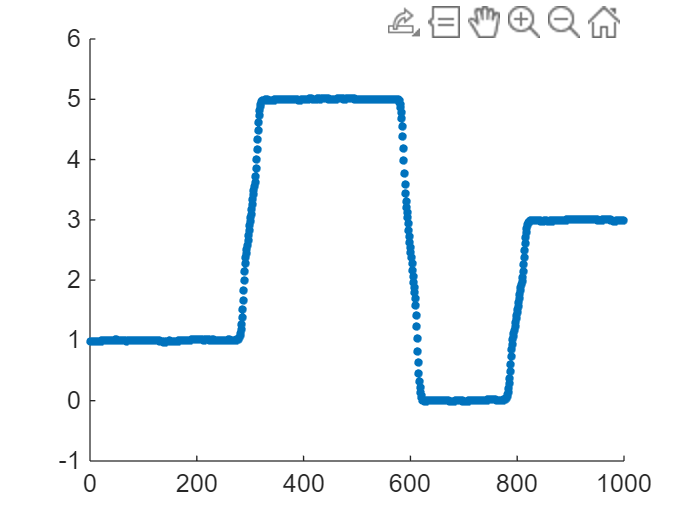

% Plot the denoised data
scatter(1:length(X), X, 10, 'filled');



% full algorithm: 8
% each gradient method: 100, 48, 79, 26, 27, 68, 37, 1
% 
% execution time: 150.9539 seconds